close all
clear all
clc


%%%% Define the parameters in the system
M = 0.1; %[kg]
m = 0.01; %[kg]
Kt = 0.0301; %[Nm/A]
Kb = 0.0301; %[Vs/rad]
C = 8.35*10^-5; %[kgm^2/s]
R = 6.5; %[ohm]
a = 0.02; %[m]


s = tf('s');


% (1) Define our transfer function 
Gs_Mechane = [(a^2)*R*(M+m) (Kt*Kb +C*R) 0];
Gs = tf([a*Kt],Gs_Mechane);

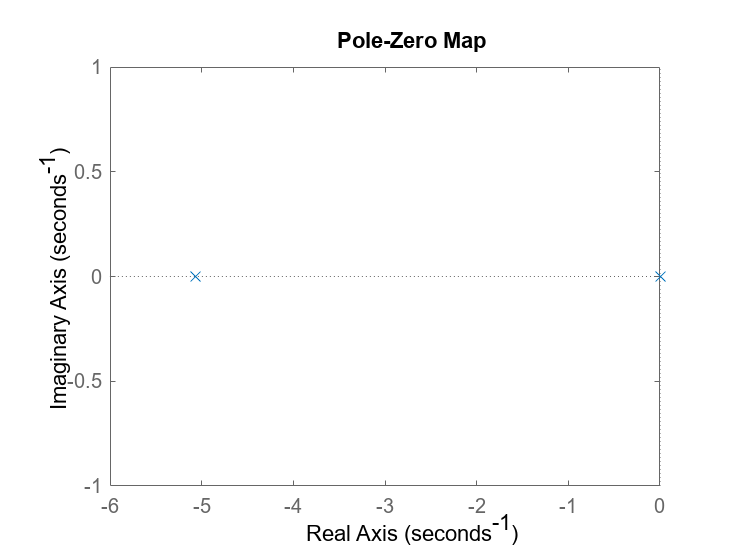

ngrid
controlSystemDesigner('nichols',Gs); %nichols_plot
pzplot(Gs); % poles & zeros map

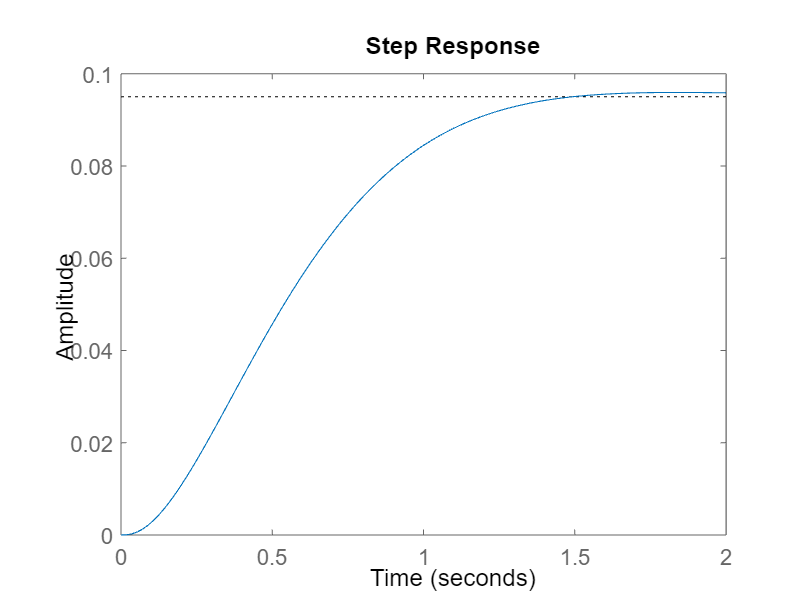

%%%%%%% (2) - find proportional controller

xr = 0.095;
Fs_Mone = [55];
Fs_Mechane = [1 55];
Fs = tf(Fs_Mone,Fs_Mechane); 
Cs = 4.465; %proportional controller
h1 = Fs*feedback(Cs*Gs,1); % x/xr 
h2 = (Fs/Gs)*feedback(Cs*Gs,1); % U/xr 
step(xr*h1);

inf1 = stepinfo(xr*h1)

inf1 = struct with fields:
         RiseTime: 0.8394
    TransientTime: 1.3149
     SettlingTime: 1.3149
      SettlingMin: 0.0859
      SettlingMax: 0.0959
        Overshoot: 0.9967
       Undershoot: 0
             Peak: 0.0959
         PeakTime: 1.8364


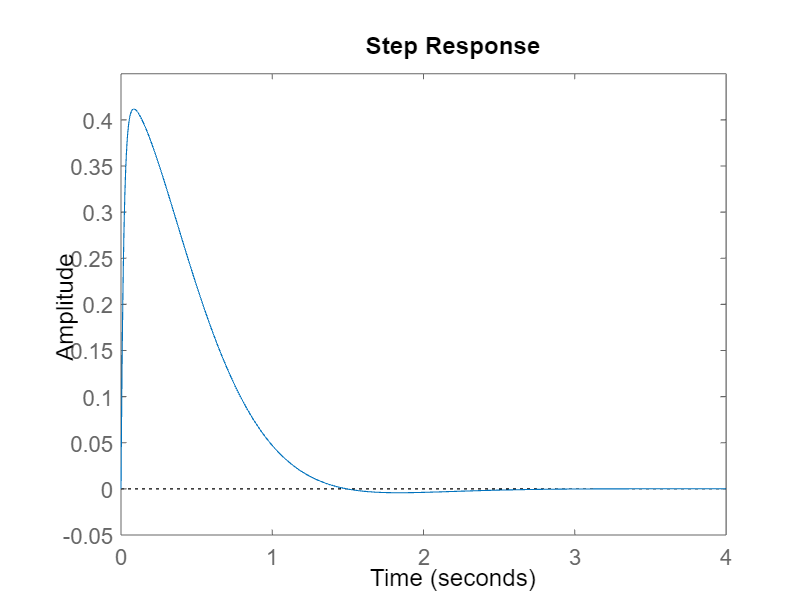

step(xr*h2);

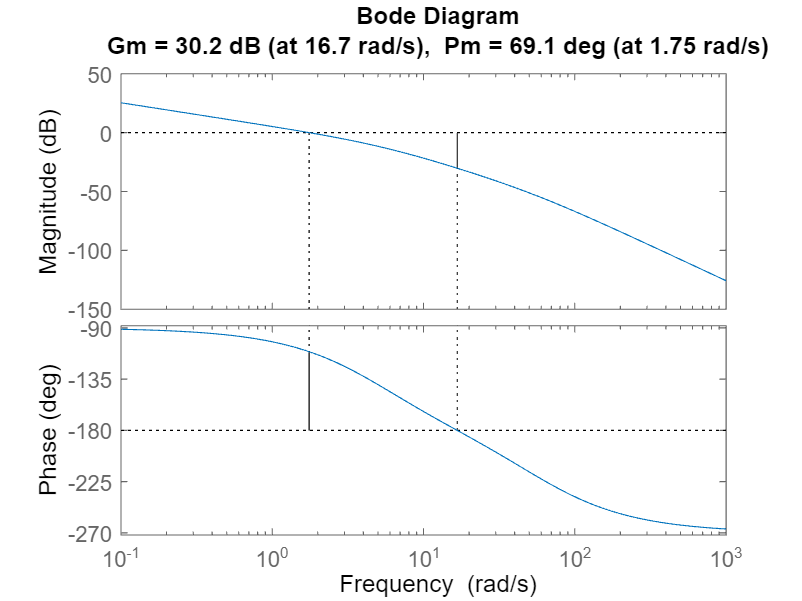

inf2 = stepinfo(h2);
margin(Fs*Cs*Gs);

%%%%%%% (3) - proportional and D_lead controller

Cs=4.465;
h1 = Fs*feedback(Cs*Gs,1);
step(xr*h1);
inf1 = stepinfo(xr*h1)

inf1 = struct with fields:
         RiseTime: 0.8394
    TransientTime: 1.3149
     SettlingTime: 1.3149
      SettlingMin: 0.0859
      SettlingMax: 0.0959
        Overshoot: 0.9967
       Undershoot: 0
             Peak: 0.0959
         PeakTime: 1.8364


hold on

for Cs= 10:5:20
    
    h1 = Fs*feedback(Cs*Gs,1);
    step(xr*h1);
    inf1 = stepinfo(xr*h1)

    

end

inf1 = struct with fields:
         RiseTime: 0.3822
    TransientTime: 1.2907
     SettlingTime: 1.2907
      SettlingMin: 0.0859
      SettlingMax: 0.1068
        Overshoot: 12.4445
       Undershoot: 0
             Peak: 0.1068
         PeakTime: 0.8364


inf1 = struct with fields:
         RiseTime: 0.2779
    TransientTime: 1.5029
     SettlingTime: 1.5029
      SettlingMin: 0.0858
      SettlingMax: 0.1143
        Overshoot: 20.3273
       Undershoot: 0
             Peak: 0.1143
         PeakTime: 0.6364


inf1 = struct with fields:
         RiseTime: 0.2259
    TransientTime: 1.3146
     SettlingTime: 1.3146
      SettlingMin: 0.0884
      SettlingMax: 0.1199
        Overshoot: 26.1998
       Undershoot: 0
             Peak: 0.1199
         PeakTime: 0.5455


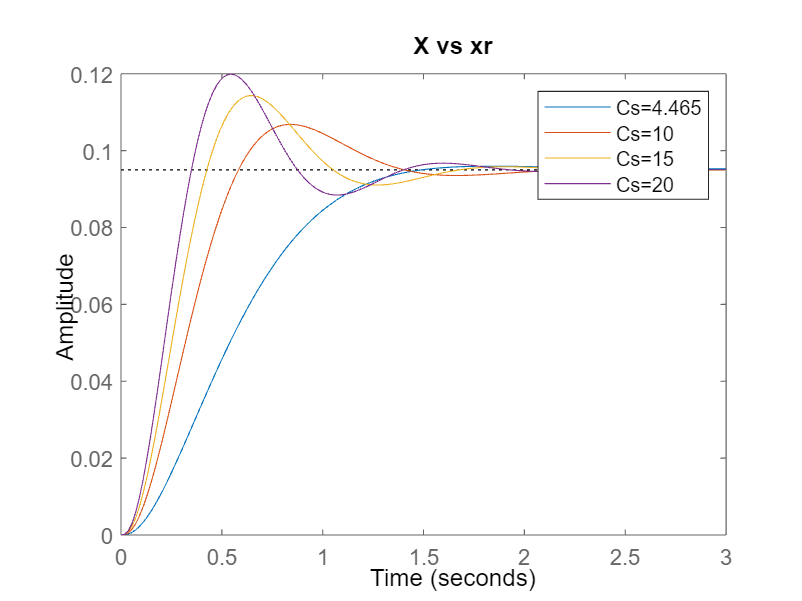

    legend('Cs=4.465','Cs=10','Cs=15','Cs=20')
    title('X vs xr')
    hold off

Cs=4.465;
h2 = (Fs/Gs)*feedback(Cs*Gs,1);
step(xr*h2);
inf2 = stepinfo(xr*h2)

inf2 = struct with fields:
         RiseTime: 0
    TransientTime: 1.3184
     SettlingTime: NaN
      SettlingMin: -0.0042
      SettlingMax: 0.4118
        Overshoot: Inf
       Undershoot: Inf
             Peak: 0.4118
         PeakTime: 0.0854


hold on

        
for Cs= 10:5:20     
    h2 = (Fs/Gs)*feedback(Cs*Gs,1);
    step(xr*h2);
    inf2 = stepinfo(xr*h2)

    
end

inf2 = struct with fields:
         RiseTime: 0
    TransientTime: 1.2953
     SettlingTime: NaN
      SettlingMin: -0.1182
      SettlingMax: 0.9031
        Overshoot: Inf
       Undershoot: Inf
             Peak: 0.9031
         PeakTime: 0.0737


inf2 = struct with fields:
         RiseTime: 0
    TransientTime: 1.5124
     SettlingTime: NaN
      SettlingMin: -0.2900
      SettlingMax: 1.3345
        Overshoot: Inf
       Undershoot: Inf
             Peak: 1.3345
         PeakTime: 0.0670


inf2 = struct with fields:
         RiseTime: 0
    TransientTime: 1.3203
     SettlingTime: NaN
      SettlingMin: -0.4978
      SettlingMax: 1.7565
        Overshoot: Inf
       Undershoot: Inf
             Peak: 1.7565
         PeakTime: 0.0636


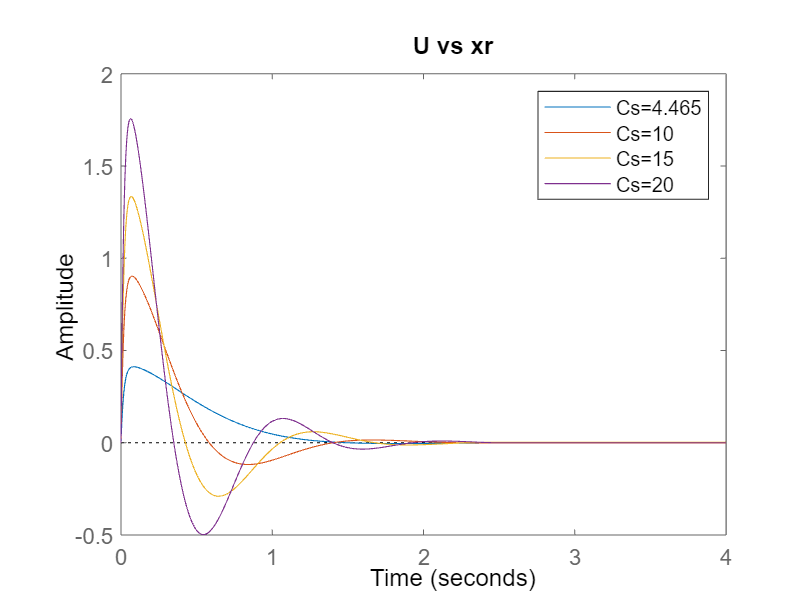


legend('Cs=4.465','Cs=10','Cs=15','Cs=20')
title('U vs xr')
hold off

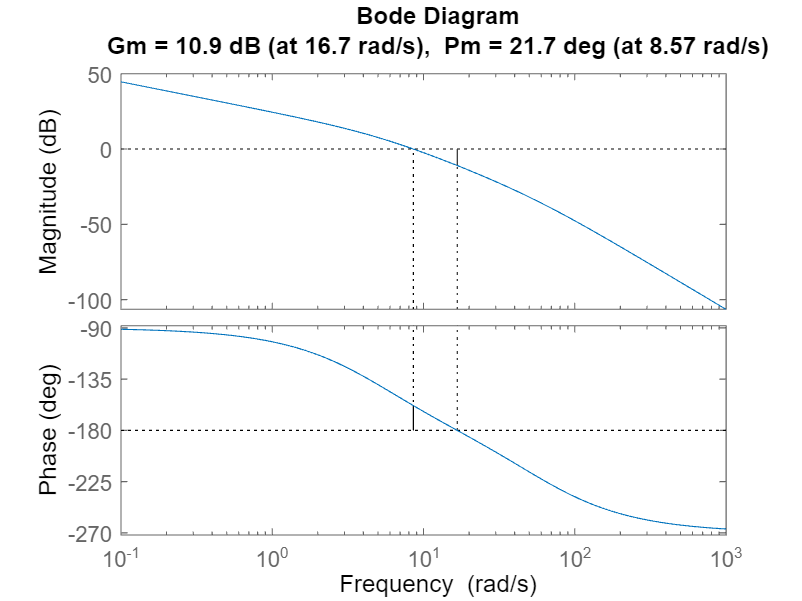


Cs2=41;
margin(Fs*Cs2*Gs);

Cs2=41;
mone_d = [1.42 8.57];
mechane_d = [1 12.16];
Dl = tf(mone_d,mechane_d); % Dlead +33.5 deg

C_t= Cs2*((Dl)^2)

C_t =
 
  82.67 s^2 + 997.9 s + 3011
  --------------------------
    s^2 + 24.32 s + 147.9
 
Continuous-time transfer function.



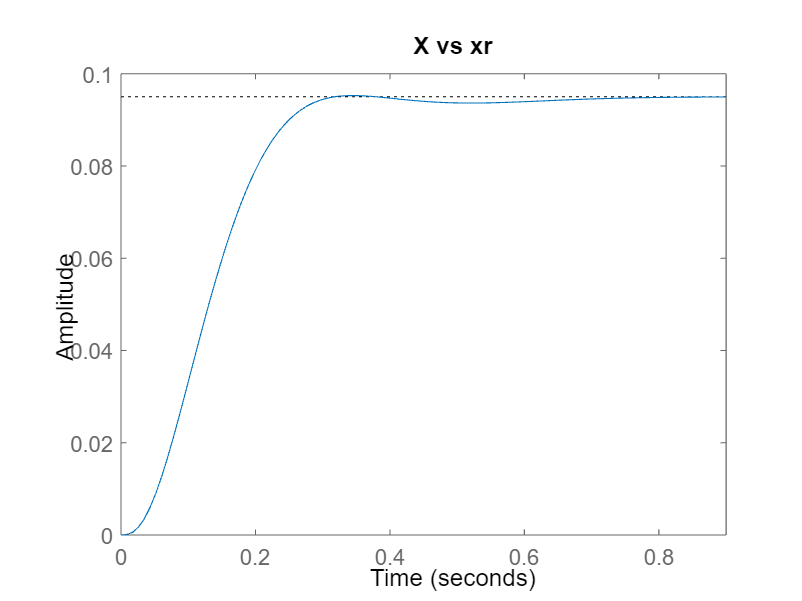


h3 = Fs*feedback(C_t*Gs,1);
step(xr*h3);
title('X vs xr')


inf3 = stepinfo(xr*h3)

inf3 = struct with fields:
         RiseTime: 0.1718
    TransientTime: 0.2781
     SettlingTime: 0.2781
      SettlingMin: 0.0856
      SettlingMax: 0.0953
        Overshoot: 0.2866
       Undershoot: 0
             Peak: 0.0953
         PeakTime: 0.3467


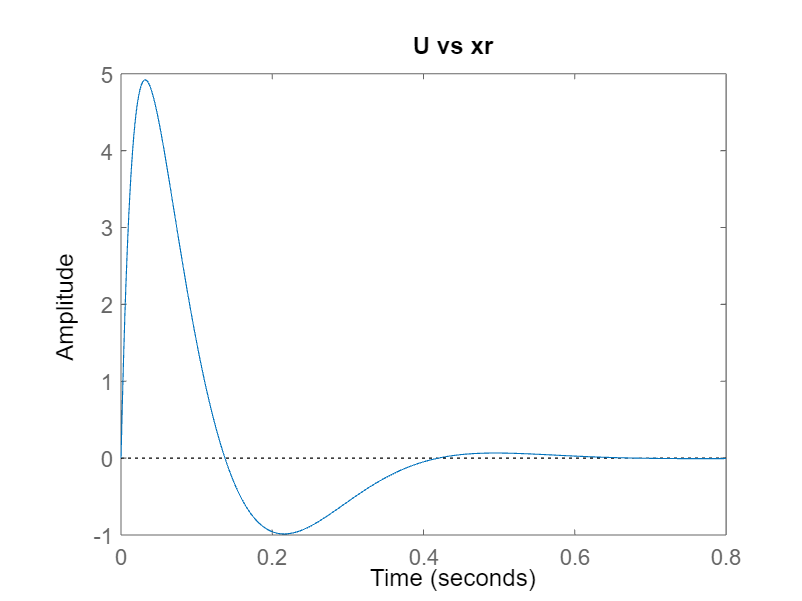


h4 = (Fs/Gs)*feedback(C_t*Gs,1);
step(xr*h4);
title('U vs xr')

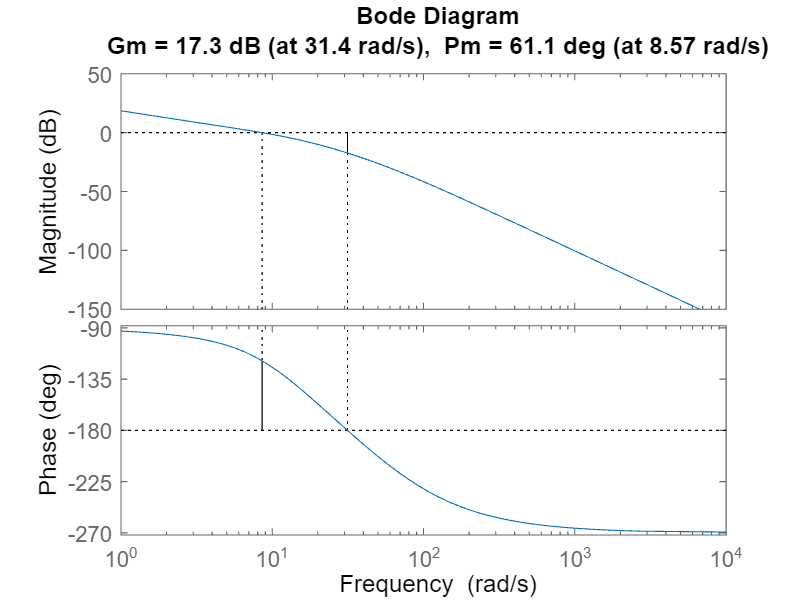


margin(Fs*C_t*Gs);

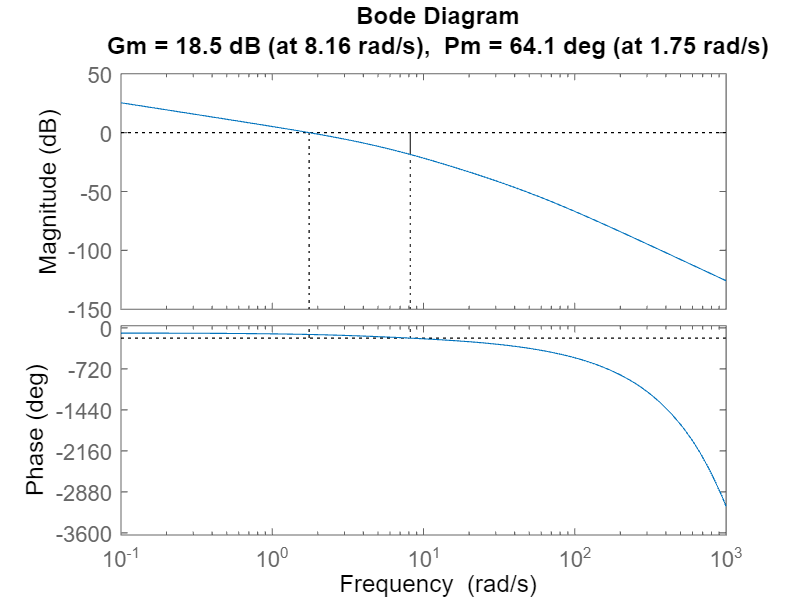

%%%%%%% 4- delay
Cs=4.465;
h = 0.05; % delay 0.05 sec
ds = exp(-h*s);
margin(Fs*Cs*Gs*ds);

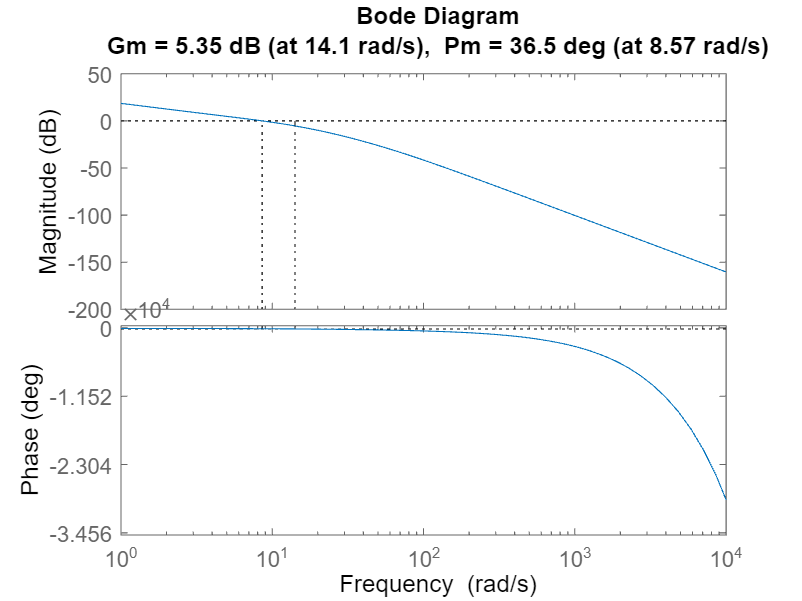

margin(Fs*C_t*Gs*ds);

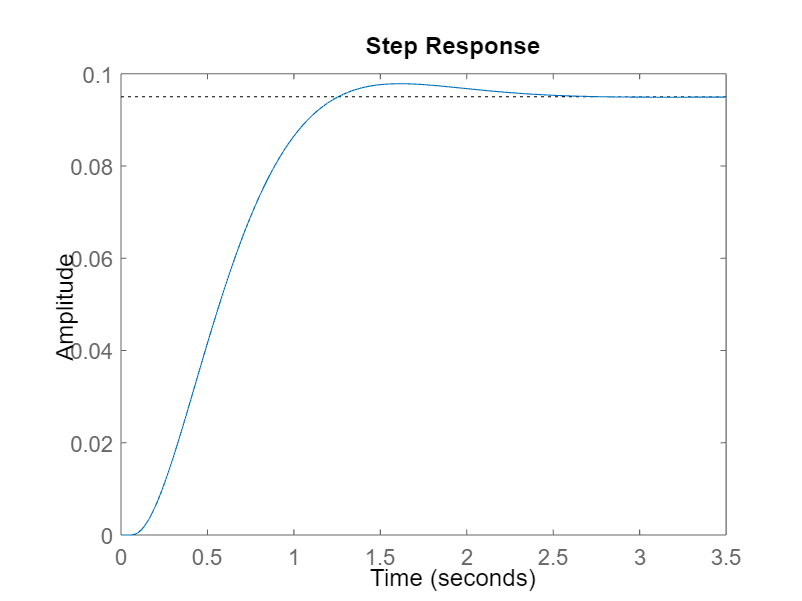




h5 = Fs*feedback(Cs*Gs*ds,1); %controller from (2)  
h6 = Fs*feedback(C_t*Gs*ds,1); %controller from (3)  
step(xr*h5);

inf5 = stepinfo(h5)

inf5 = struct with fields:
         RiseTime: 0.7467
    TransientTime: 1.9664
     SettlingTime: 1.9664
      SettlingMin: 0.9054
      SettlingMax: 1.0299
        Overshoot: 2.9866
       Undershoot: 0
             Peak: 1.0299
         PeakTime: 1.6083


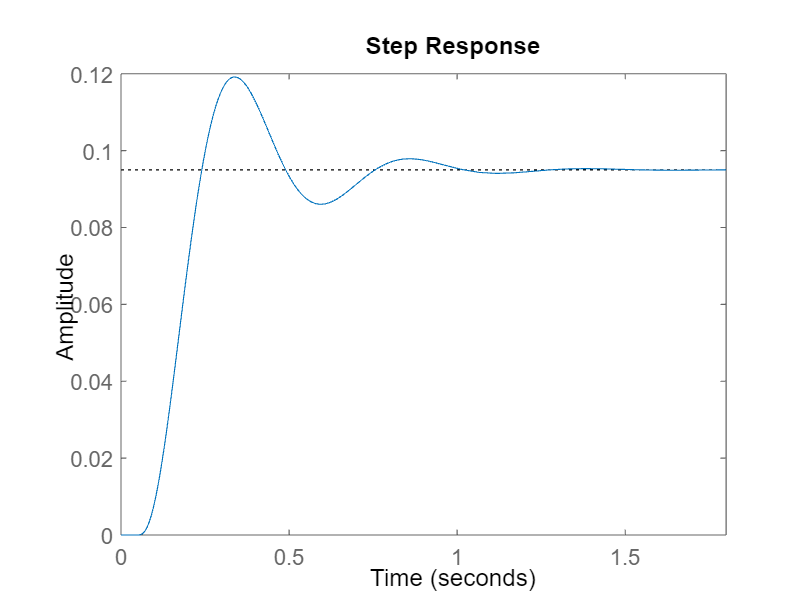

step(xr*h6);

inf6 = stepinfo(h6)

inf6 = struct with fields:
         RiseTime: 0.1207
    TransientTime: 0.9328
     SettlingTime: 0.9328
      SettlingMin: 0.9057
      SettlingMax: 1.2542
        Overshoot: 25.4176
       Undershoot: 0
             Peak: 1.2542
         PeakTime: 0.3413


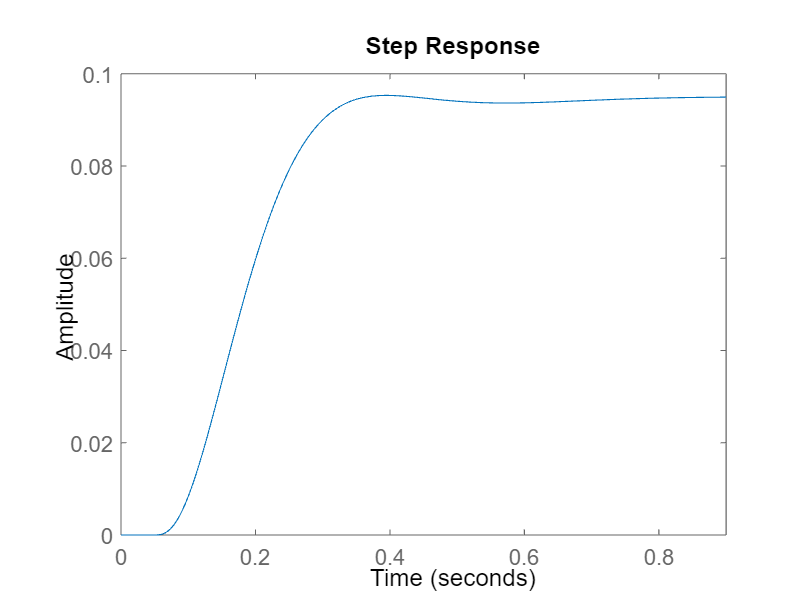

%%%%%% 5- 
C_t= Cs2*(Dl^2);
Pi= Gs*(1-ds);
C_DTC= feedback(C_t,Pi); %%%DTC


h7 = Fs*feedback((C_DTC)*Gs*ds,1); % x/xr new
step(xr*h7);

inf7 = stepinfo(xr*h7)

inf7 = struct with fields:
         RiseTime: 0.1718
    TransientTime: 0.3279
     SettlingTime: 0.3279
      SettlingMin: 0.0861
      SettlingMax: 0.0953
        Overshoot: 0.3204
       Undershoot: 0
             Peak: 0.0953
         PeakTime: 0.3947


h8 = minreal(xr*(Fs*C_DTC)/(1+Gs*C_DTC*ds)); %U

1 state removed.


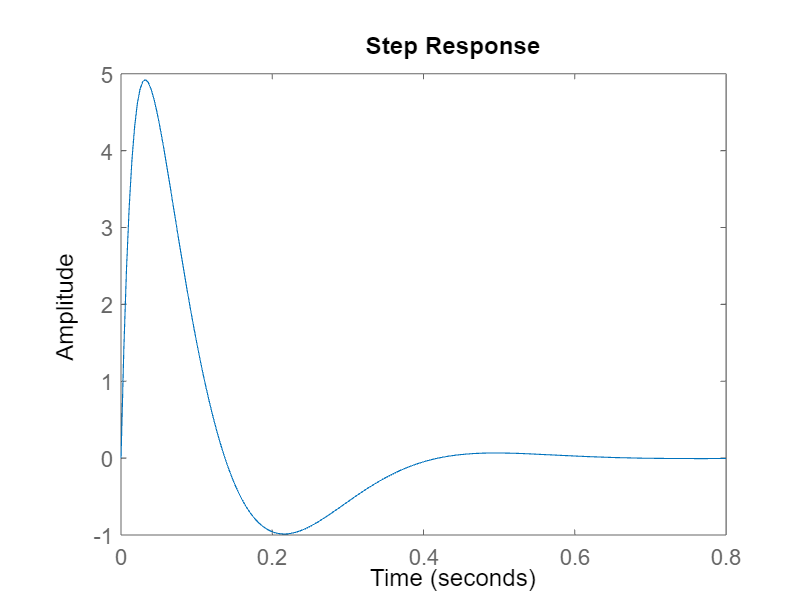

%h10 = minreal(xr*(Fs*C_t)/(1+Gs*C_t)); % U - just to make sure same
step(h8);

inf8= stepinfo(h8)

inf8 = struct with fields:
         RiseTime: 7.5820e-07
    TransientTime: 0.3849
     SettlingTime: 1.6237
      SettlingMin: -0.9871
      SettlingMax: 4.9223
        Overshoot: 1.2023e+06
       Undershoot: 2.4113e+05
             Peak: 4.9223
         PeakTime: 0.0325


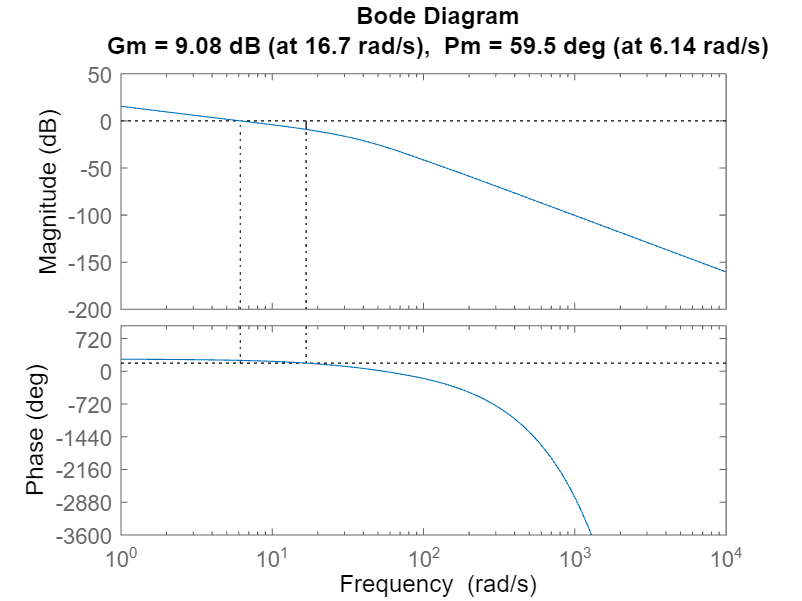

margin(Fs*C_DTC*Gs*ds);
ylim([-3600,1000])

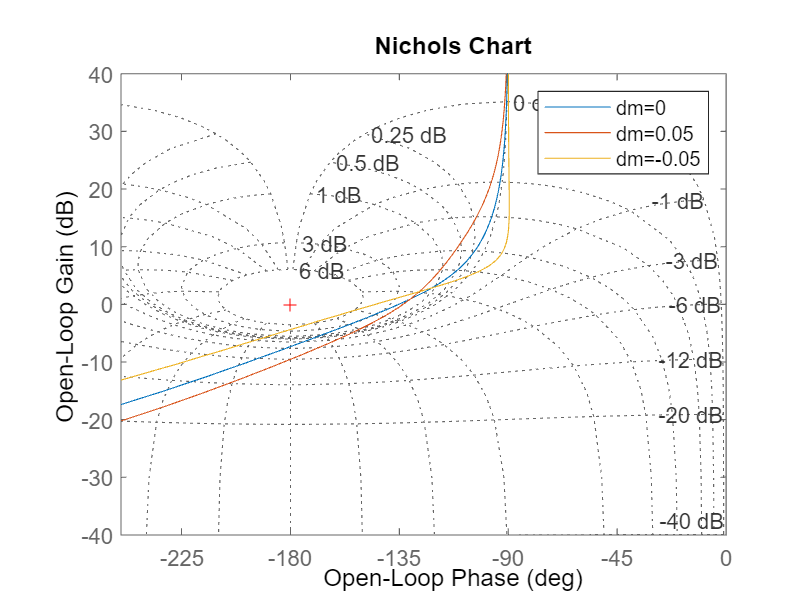

%%%%%%6 - uncertainty of mass
A = Kt/(a*R);
B = (Kt*Kb)/((a^2)*R) + (C)/(a^2);

%part 1  - C_t= Cs2*((Dl)^2)
delta_max0 = 0.05;
T00 = feedback(C_t*Gs*ds,1); % T0(s) 
lm_w0 = minreal(((M + m- delta_max0)*s+B)/(delta_max0*s)); % lm(s)^-1 %%%%

Ps_Den2 = [((M + m +0.05)/A) (B/A) 0];
Ps2 = tf([1],Ps_Den2);
Ps_Den3 = [((M + m -0.05)/A) (B/A) 0];
Ps3 = tf([1],Ps_Den3);
nichols(C_t*Gs*ds);
hold on
nichols(C_t*Ps2*ds);
nichols(C_t*Ps3*ds);
grid;
legend('dm=0', 'dm=0.05', 'dm=-0.05');
xlim([-250,0])
hold off

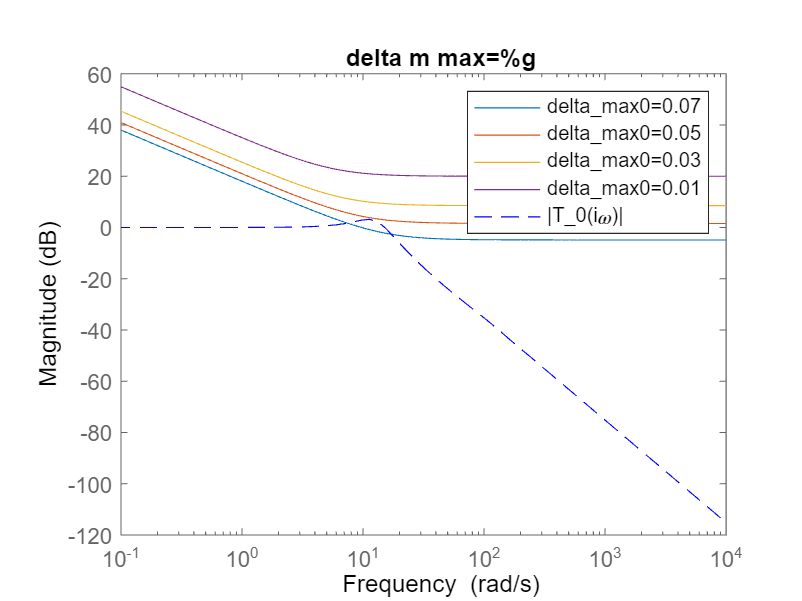


for delta_max0 = 0.07:-0.02:0.01
    lm_w0 = minreal(((M + m- delta_max0)*s+B)/(delta_max0*s));
    bodemag(lm_w0);
    hold on
    %legend('delta_max0=0.01','delta_max0=0.03','delta_max0=0.05','delta_max0=0.07');
    title('delta m max=%g','delta_max0');
    %'1/l_m(\omega)'
   
end
bodemag(T00,'--');
legend('delta_max0=0.07','delta_max0=0.05','delta_max0=0.03','delta_max0=0.01','|T_0(i\omega)|');
hold off

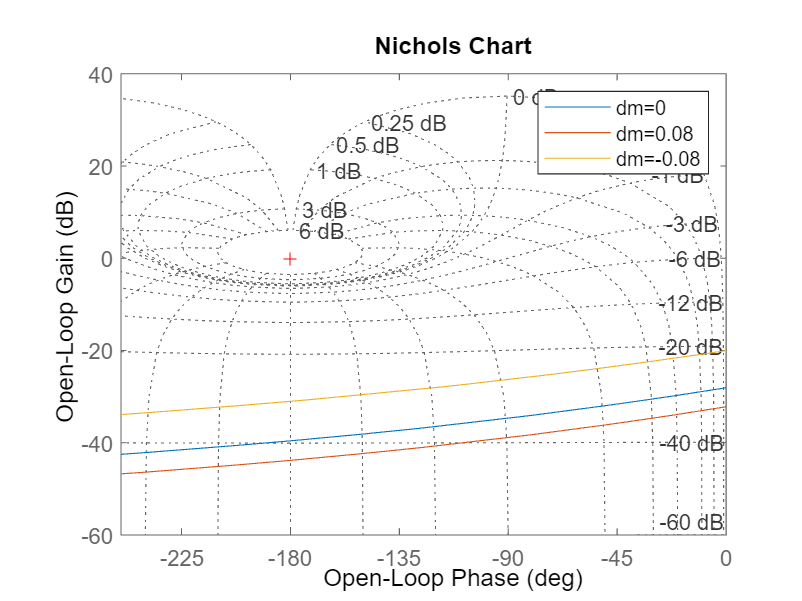


% part 2  -  C_DTC= feedback(C_t,Pi) 
delta_max1 = 0.08; 
T01 = minreal((C_t*Gs*ds)/(1+C_t*Gs));% T0(s)
lm_w1 = minreal(((M+m - delta_max1)*s+B)/(delta_max1*s)); % lm(s)^-1
Ps_Den4 = [((M+m+0.07)/A) (B/A) 0];
Ps4 = tf([1],Ps_Den4);
Ps_Den5 = [((M+m-0.07)/A) (B/A) 0];
Ps5 = tf([1],Ps_Den5);
nichols(C_DTC*Gs*ds);%%%%%%%%%
hold on
nichols(C_DTC*Ps4*ds);
nichols(C_DTC*Ps5*ds);
grid;
xlim([-250,0])
legend('dm=0', 'dm=0.08', 'dm=-0.08');
hold off

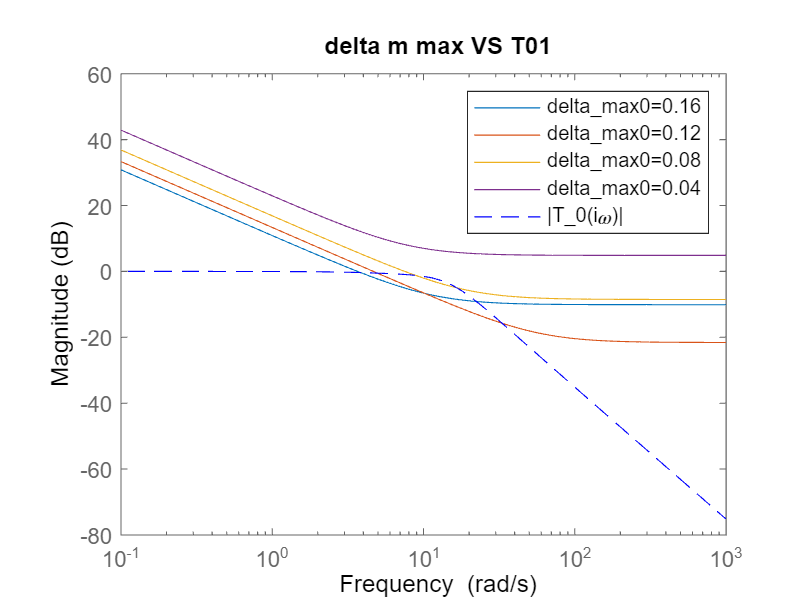


for delta_max1 = 0.16:-0.04:0.04
    lm_w1 = minreal(((M+m - delta_max1)*s+B)/(delta_max1*s));
    bodemag(lm_w1);
    hold on
    title(sprintf('delta m max VS T01',delta_max1));

end
bodemag(T01,'--');
legend('delta_max0=0.16','delta_max0=0.12','delta_max0=0.08','delta_max0=0.04','|T_0(i\omega)|');
hold off

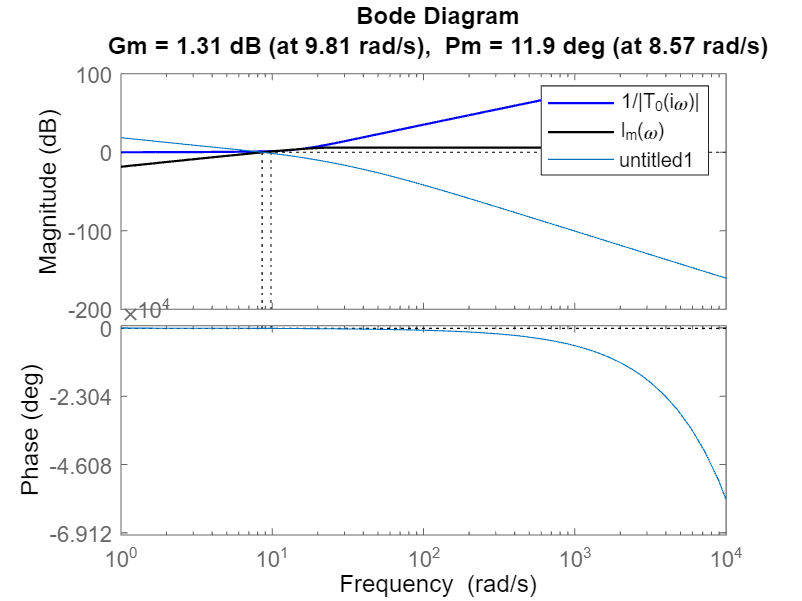

%%%%part 7 - uncertainty in delay

wi=0.1;  %making a graph
wf=1000;
dw=0.01;
w=wi:dw:wf;
delta_max2 = 0.12;
w2=wi:dw:(pi/delta_max2);
w3=((pi/delta_max2)+dw):dw:wf;

% margin(Fs*C_t*Gs*ds); %% calculate D.M
PM = 59.1;
Wc = 6.14;
DM = (PM * (pi/180))/Wc;

T02 = minreal((1+1/(C_t*Gs))); % T02 = T01^-1;
lm_w2 = 2*abs(sin((w2*delta_max2)/2)); % lm 
lm_w3 = 2 + w3*0; % w3*0 - A negligible part because the function 'lm_w3' must be a function of w
[mag,ph]=bode(T02,w);
mag1D=mag(:);


figure;
semilogx(w,20*log10(mag1D),'-b','linewidth',1); grid;
hold on;
semilogx(w2,20*log10(lm_w2),'-k','linewidth',1);
semilogx(w3,20*log10(lm_w3),'-k','linewidth',1);
legend('1/|T_0(i\omega)|', 'l_m(\omega)');
xlabel('frequency [r/s]');
ylabel('magnitude [dB]');
title(sprintf('delta h max=%g',delta_max2));


%nichols(C_t*Gs*(exp(-h*s)));%%%%%%%%%%%%%%%%%%%%%
%hold on
%nichols(C_t*Gs*(exp(-(h-0.005)*s)));
%nichols(C_t*Gs*(exp(-(h+0.044)*s)));
%nichols(C_t*Gs*(exp(-(h+0.06)*s)));
%ngrid;
%legend('h=0.05', '1/l_m(\omega)');

dh = 0.1; %the sum max is =0.1
ds2 = exp(-dh*s);
margin(Fs*C_t*Gs*ds2);
hold off

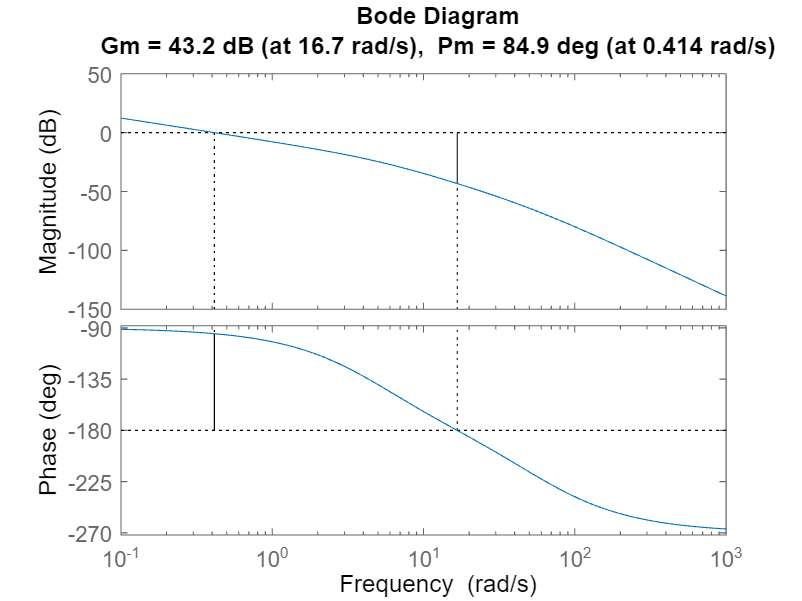

%%%%% (8) bonus
t = 0:0.0001:150;
xrh = 0.125*sin(7*t); 
margin(Fs*Gs);

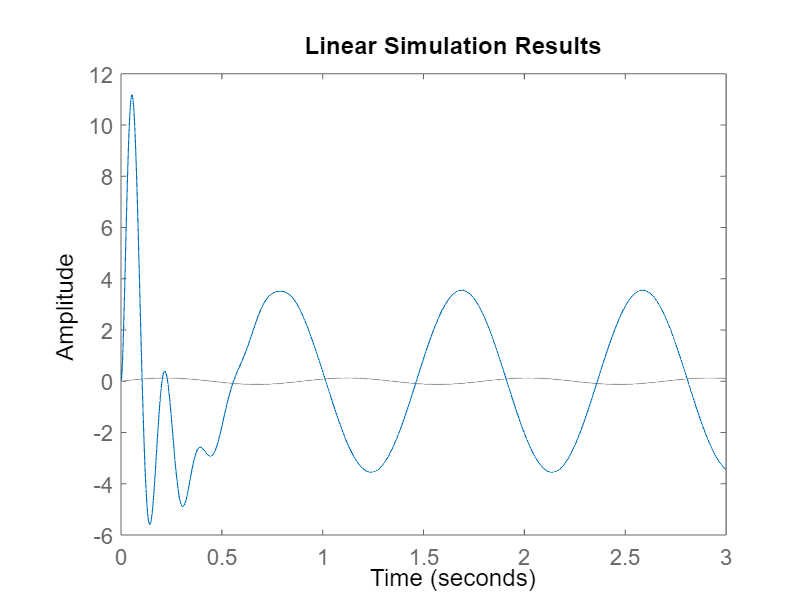

Cn=minreal(70*(s)/(0.1*s+1)); % i didnt success
pcl = Fs*feedback(Gs*Cn,1);
Pu = minreal((Fs*Cn - pcl*Cn)); % U/xr 
figure(1);
lsim(Pu, xrh, t);
txt = {'U'};
text(0.4,65,txt);
xlim([0,3])

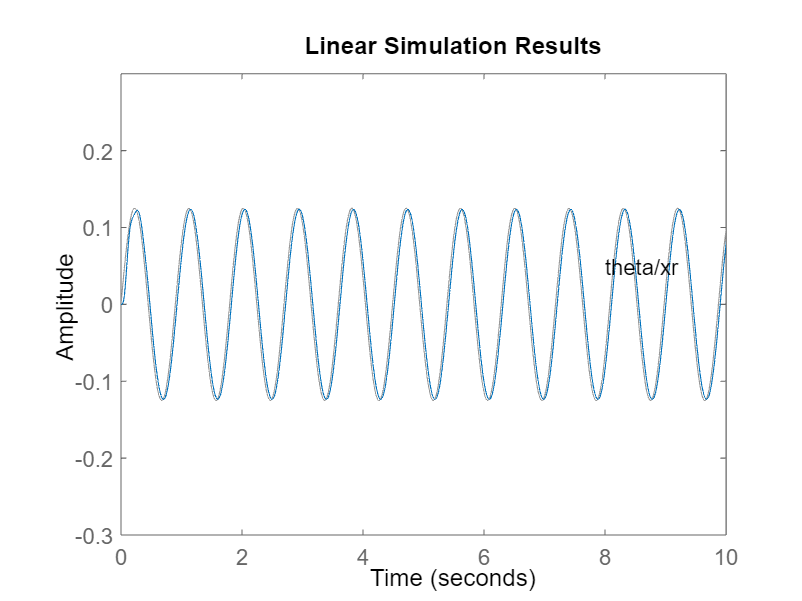

figure(2);
lsim(pcl, xrh, t);
ylim([-0.3 0.3]);
xlim([0 10]);
txt = {'theta/xr'};
text(8,0.05,txt);

%% part 10
%%%%% 
l = 0.23;
g = 9.81;
alpha = R*a/Kt;
beta = (R*C+Kt*Kb)/(Kt*a);

Gux = tf([l 0 g],[alpha*M*l beta*l alpha*(M+m)*g beta*g 0]);
Gxt = tf([1 0 0],[l 0 g]);
Cs3 = 2.5;
Gzt = minreal((Cs3*Gux*Gxt)/(1+Cs3*Gux));

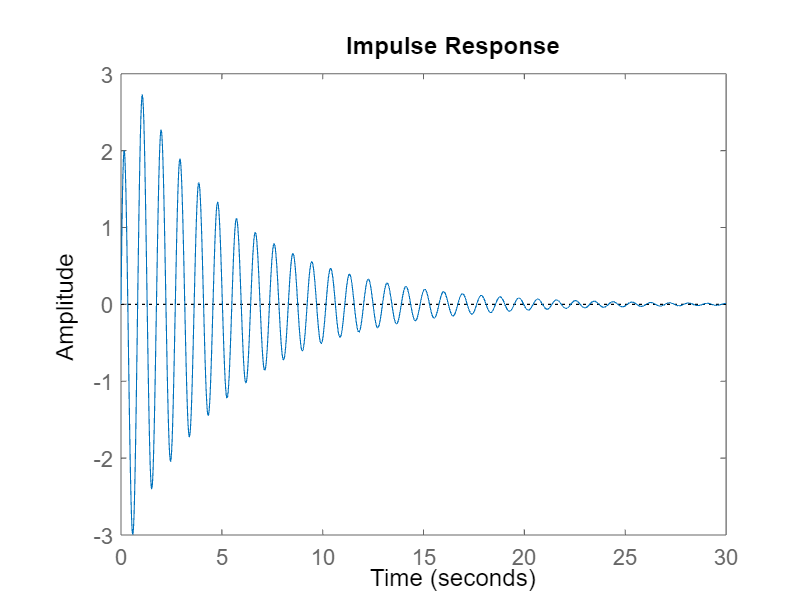

%%
%%%%% (11)

%rlocus(Gzt);  
p1 = pole(Gzt); %poles and zeros
z1 = zero(Gzt);
impulse(Gzt);
txt = {'Gzt = theta/z', 'Cx = 2.5'};
text(1,40,txt)

inf= stepinfo(impulse(Gzt));

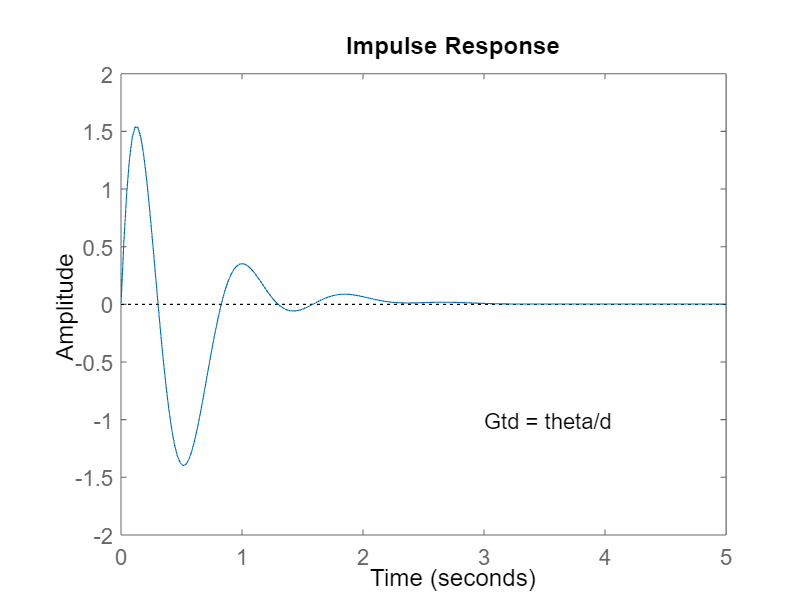

Ctheta = (2.6*s+20)/(0.2*s+20); % pd controller
Gtd = minreal(Gzt/(1+Ctheta*Gzt));
% nichols(Gzt);
% ngrid

figure(1)
impulse(Gtd);
ylim([-2 2]);
xlim([0 5]);
txt = {'Gtd = theta/d'};
text(3,-1,txt)

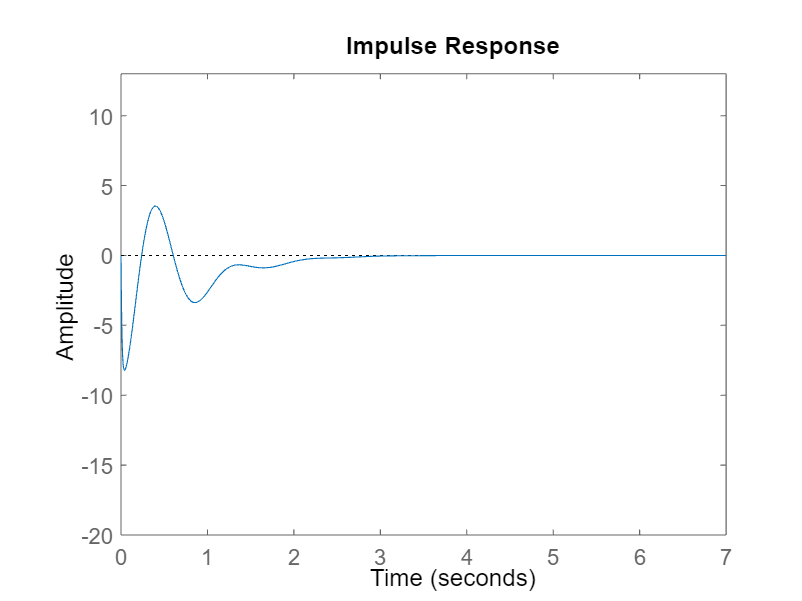


Gud = minreal((Cs3)/((1+Cs3*Gux*(1+Gxt*Ctheta))));
figure(2);
impulse(Gud);
ylim([-20 13]);
xlim([0 7]);


% % % acc loop
% % % for i = 1:50
% % %     figure(i);
% % %     Ctheta = 1+0.05*i+(0.15*s)/(0.005*s+1);
% % %     Gtd = (Gzt/(1+Ctheta*Gzt));
% % %     Gud = (Cs3)/((1+Cs3*Gux*(1+Gxt*Ctheta)));
% % %     impulse(Gtd);
% % %     hold on
% % %     impulse(Gud); 
% % % end

%%%%% (12)
Gux2 = tf([l 0 -g],[alpha*M*l beta*l -alpha*(M+m)*g -beta*g 0]);
Gxt2 = tf([1 0 0],[l 0 -g]);

Gut = minreal(Gux2*Gxt2);

Gut =
 
               10.07 s
  ---------------------------------
  s^3 + 5.572 s^2 - 46.92 s - 237.7
 
Continuous-time transfer function.



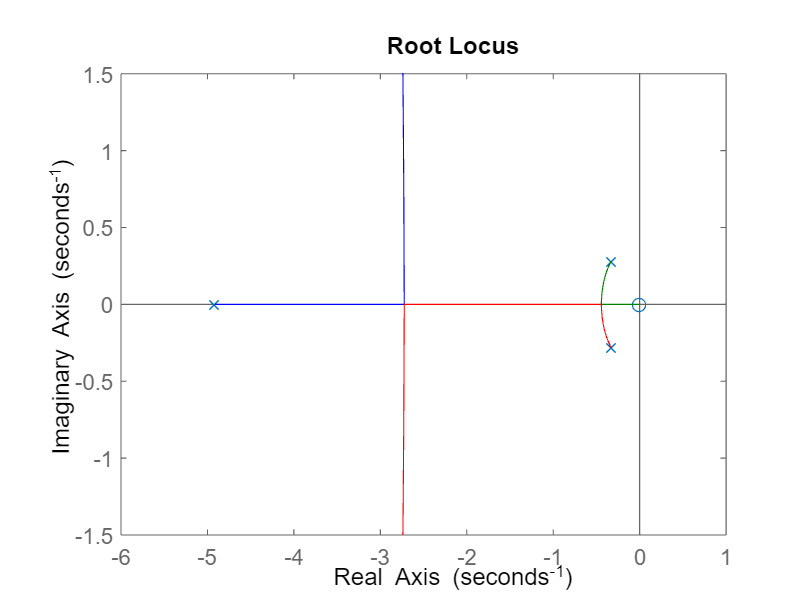

% rlocus(Gut);
% Clpf = 4.3/(s+5);  % Low Pass Filter
Cnew = (5*s+23.7)/s; 
Gdt2 = minreal(Gut/(1+Cnew*Gut));
% nichols(Gut);  % open loop
% ngrid
rlocus(Gdt2);

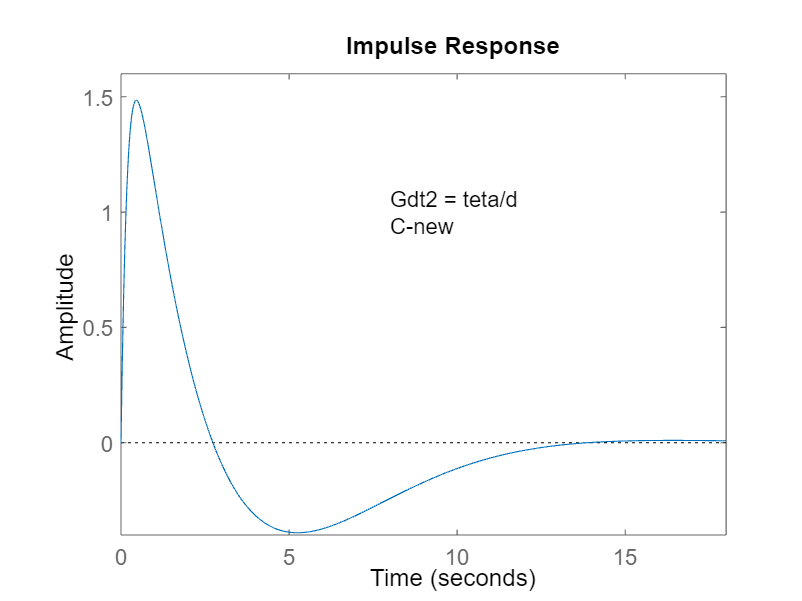

impulse(Gdt2);
txt = {'Gdt2 = teta/d','C-new'};
text(8,1,txt);